data = readtable('Salary Data.csv'); 

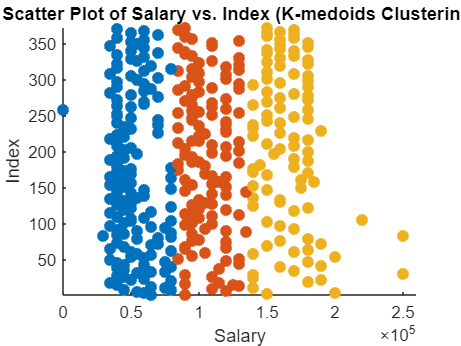

salary = data.Salary;
indices = 1:numel(salary);
k = 3; 
medoids_idx = randsample(numel(salary), k);
medoids = salary(medoids_idx);

distances = abs(bsxfun(@minus, salary, medoids'));
[~, clusters] = min(distances, [], 2);
cluster_colors = lines(k);  

figure;
scatter(salary, indices, 50, cluster_colors(clusters, :), 'filled');  % Plot each salary point with its corresponding index
title('Scatter Plot of Salary vs. Index (K-medoids Clustering)');
xlabel('Salary');
ylabel('Index');

xlim([0, max(salary) + 10000]);  
ylim([1, numel(salary)]);  